# Analysis Transmitter Designs 1_2 to 1_5 

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_CNN_height_38um_Q_5_uL_tetrazine_Design_1');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_CNN_height_38um_Q_5_uL_tetrazine_Design_1


#### Parameters

%call to the parameters file
Parameters

p0=0.44146 mbar


c_Tartrazine_ini = 0.0845

c_max = 0.0845

mu = 9.9792e-04

D_coeff = 4.9000e-10

Q_inlet_CNN=2.2 uL/min


### Experimental Work

Description: This block evaluates the experimental work from the following designs

- Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min

- Design_1_3_microfluidic_pipes_14_Oct_2025_5_uL_min

- Design_1_4_microfluidic_pipes_14_Oct_2025_5_uL_min

- Design_1_5_microfluidic_pipes_14_Oct_2025_5_uL_min

### Evaluating the conversion constants from intensity to concentration

% Load a video file for image processing
%Design_1_2
videoFileName_Design_1_2 = fullfile(pwd,...
    'experimental_work/Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min/',...
    'Transmitter_1_5_s (1).mp4');
videoObject_Design_1_2 = VideoReader(videoFileName_Design_1_2);
%Design_1_3
videoFileName_Design_1_3 = fullfile(pwd,...
    'experimental_work/Design_1_3_microfluidic_pipes_14_Oct_2025_5_uL_min/',...
    'Transmitter_1_5_s (1).mp4');
videoObject_Design_1_3 = VideoReader(videoFileName_Design_1_3);
%Design_1_4
videoFileName_Design_1_4 = fullfile(pwd,...
    'experimental_work/Design_1_4_microfluidic_pipes_14_Oct_2025_5_uL_min/',...
    'Transmitter_1_5_s (1).mp4');
videoObject_Design_1_4 = VideoReader(videoFileName_Design_1_4);
%Design_1_5
videoFileName_Design_1_5 = fullfile(pwd,...
    'experimental_work/Design_1_5_microfluidic_pipes_14_Oct_2025_5_uL_min/',...
    'Transmitter_1_5_s (1).mp4');
videoObject_Design_1_5 = VideoReader(videoFileName_Design_1_5);

% Get video properties
frameRate = videoObject_Design_1_2.FrameRate

frameRate = 60

totalFrames = floor(videoObject_Design_1_2.Duration * frameRate);

fprintf('Total number of frames: %d\n', totalFrames);

Total number of frames: 995



% Define start and end time (in seconds)
startTime_Tx = 1;  % e.g., start at 4 seconds
endTime_Tx   = 10; % e.g., end at 10 seconds

% Set the video reader to the start time
videoObject_Design_1_2.CurrentTime = startTime_Tx;

% Initialize cell array to store frames
segmentedFrames_Design_1_2 = {};
segmentedFrames_Design_1_3 = {};
segmentedFrames_Design_1_4 = {};
segmentedFrames_Design_1_5 = {};
frameIdx = 1;

% Read frames between startTime and endTime
while hasFrame(videoObject_Design_1_2) && videoObject_Design_1_2.CurrentTime <= endTime_Tx
    frame = readFrame(videoObject_Design_1_2);
    segmentedFrames_Design_1_2{frameIdx} = frame;  %store current frame
    frame = readFrame(videoObject_Design_1_3);
    segmentedFrames_Design_1_3{frameIdx} = frame;  %store current frame
    frame = readFrame(videoObject_Design_1_4);
    segmentedFrames_Design_1_4{frameIdx} = frame;  %store current frame
    frame = readFrame(videoObject_Design_1_5);
    segmentedFrames_Design_1_5{frameIdx} = frame;  %store current frame
    frameIdx = frameIdx + 1;
end

fprintf('Stored %d frames between %.2f s and %.2f s\n', numel(segmentedFrames_Design_1_2), startTime_Tx, endTime_Tx);

Stored 541 frames between 1.00 s and 10.00 s


### Reading the Transmitter Supply

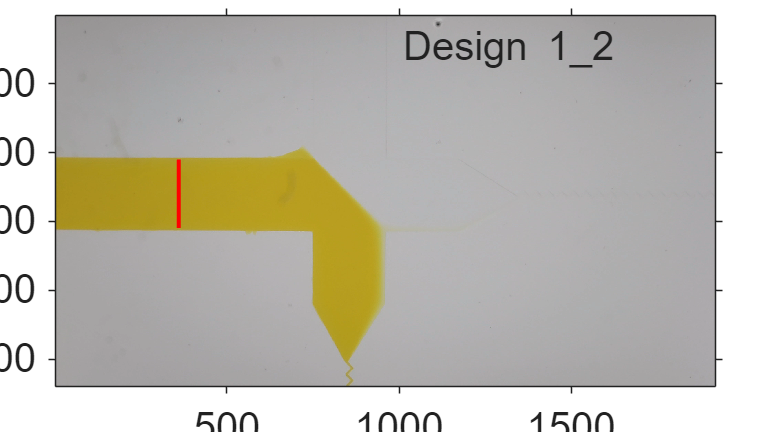

% Predefined coordinates for the line
%Design 1_2
xCoords_Inlet_CNN_Design_1_2 = [360, 360]; % X coordinates
yCoords_Outlet_CNN_Design_1_2 = [619, 420]; % Y coordinates
%Design 1_3
xCoords_Inlet_CNN_Design_1_3 = [375, 490]; % X coordinates
yCoords_Outlet_CNN_Design_1_3 = [517, 211]; % Y coordinates
%Design 1_4
xCoords_Inlet_CNN_Design_1_4 = [595, 595]; % X coordinates
yCoords_Outlet_CNN_Design_1_4 = [470, 263]; % Y coordinates
%Design 1_5
xCoords_Inlet_CNN_Design_1_5 = [336, 336]; % X coordinates
yCoords_Outlet_CNN_Design_1_5 = [803, 499]; % Y coordinates

%Design 1_2
figure; % Create a new figure window
imshow(segmentedFrames_Design_1_2{1}); % Display the first frame
axis on; % Turn on the axes
xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis
text(1000,100,"Design 1\_2",'FontSize',fontsize)
% Hold the current plot to overlay the line
hold on;
plot(xCoords_Inlet_CNN_Design_1_2, yCoords_Outlet_CNN_Design_1_2, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
hold off;
set(gca,"FontSize",fontsize)

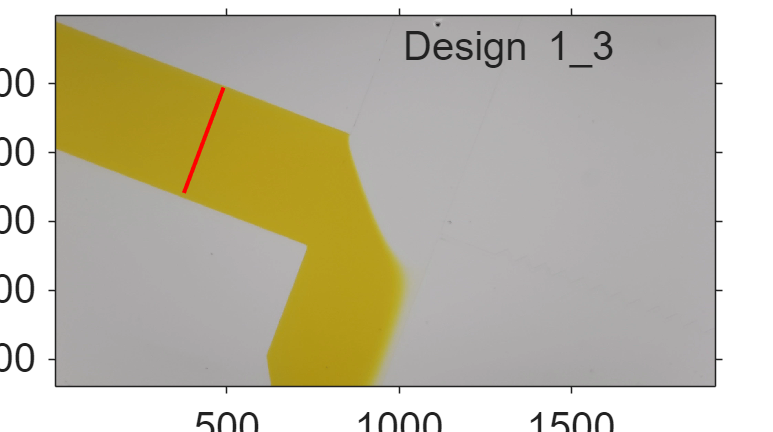


%Design 1_3
figure; % Create a new figure window
imshow(segmentedFrames_Design_1_3{1}); % Display the first frame
axis on; % Turn on the axes
text(1000,100,"Design 1\_3",'FontSize',fontsize)
xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis
% Hold the current plot to overlay the line
hold on;
plot(xCoords_Inlet_CNN_Design_1_3, yCoords_Outlet_CNN_Design_1_3, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
hold off;
set(gca,"FontSize",fontsize)

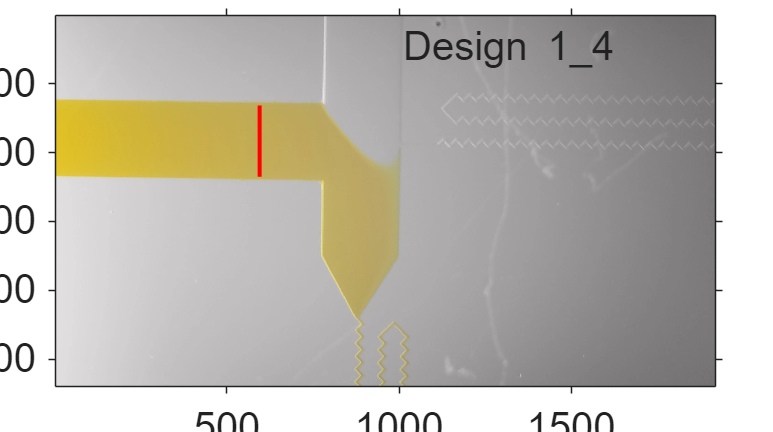


%Design 1_4
figure; % Create a new figure window
imshow(segmentedFrames_Design_1_4{1}); % Display the first frame
axis on; % Turn on the axes
text(1000,100,"Design 1\_4",'FontSize',fontsize)
xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis
% Hold the current plot to overlay the line
hold on;
plot(xCoords_Inlet_CNN_Design_1_4, yCoords_Outlet_CNN_Design_1_4, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
hold off;
set(gca,"FontSize",fontsize)

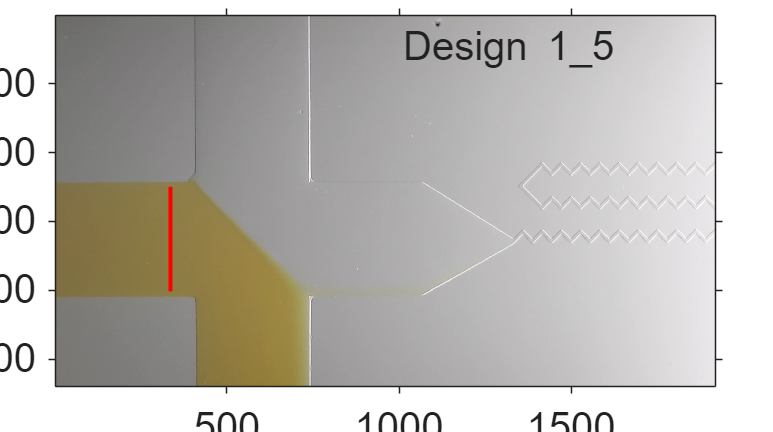


%Design 1_5
figure; % Create a new figure window
imshow(segmentedFrames_Design_1_5{1}); % Display the first frame
axis on; % Turn on the axes
text(1000,100,"Design 1\_5",'FontSize',fontsize)
xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis
% Hold the current plot to overlay the line
hold on;
plot(xCoords_Inlet_CNN_Design_1_5, yCoords_Outlet_CNN_Design_1_5, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
hold off;
set(gca,"FontSize",fontsize)

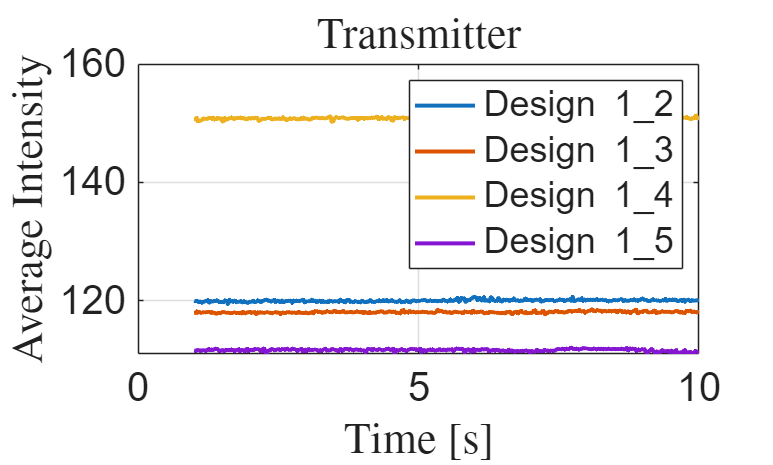


% Initialize an array to store the average intensity values
averageIntensities_Tx_Design_1_2 = zeros(1, length(segmentedFrames_Design_1_2));
averageIntensities_Tx_Design_1_3 = zeros(1, length(segmentedFrames_Design_1_3));
averageIntensities_Tx_Design_1_4 = zeros(1, length(segmentedFrames_Design_1_4));
averageIntensities_Tx_Design_1_5 = zeros(1, length(segmentedFrames_Design_1_5));

% Loop through each frame to calculate the average intensity along the line
for k = 1:length(segmentedFrames_Design_1_2)
    %Design_1_2
    frame = segmentedFrames_Design_1_2{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_Tx = improfile(frame, xCoords_Inlet_CNN_Design_1_2, yCoords_Outlet_CNN_Design_1_2);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_Tx_Design_1_2(k) = mean(lineProfile_Tx(:));

    %Design_1_3
    frame = segmentedFrames_Design_1_3{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_Tx = improfile(frame, xCoords_Inlet_CNN_Design_1_3, yCoords_Outlet_CNN_Design_1_3);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_Tx_Design_1_3(k) = mean(lineProfile_Tx(:));

    %Design_1_4
    frame = segmentedFrames_Design_1_4{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_Tx = improfile(frame, xCoords_Inlet_CNN_Design_1_4, yCoords_Outlet_CNN_Design_1_4);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_Tx_Design_1_4(k) = mean(lineProfile_Tx(:));

    %Design_1_5
    frame = segmentedFrames_Design_1_5{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_Tx = improfile(frame, xCoords_Inlet_CNN_Design_1_5, yCoords_Outlet_CNN_Design_1_5);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_Tx_Design_1_5(k) = mean(lineProfile_Tx(:));
end

% Plot average intensities over time
timeVector = linspace(startTime_Tx, endTime_Tx, length(averageIntensities_Tx_Design_1_2)); % Create a time vector
figure; % Plotting the concentration with time
plot(timeVector, averageIntensities_Tx_Design_1_2, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, averageIntensities_Tx_Design_1_3, 'LineWidth', 2);
plot(timeVector, averageIntensities_Tx_Design_1_4, 'LineWidth', 2);
plot(timeVector, averageIntensities_Tx_Design_1_5, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Average Intensity', 'Interpreter', 'latex'); % Label for Y-axis
title('Transmitter', 'Interpreter', 'latex'); % Title of the plot
legend('Design 1\_2','Design 1\_3','Design 1\_4','Design 1\_5')
grid on; % Turn on the grid
set(gca, 'FontSize', fontsize); % Set font size for axes


% Create the dataset folder if it does not exist
outputFolder = fullfile(pwd, 'dataset');

% Save the average intensity variables to a .mat file
save(fullfile(outputFolder, 'averageIntensities_Tx.mat'), ...
    'averageIntensities_Tx_Design_1_2', ...
    'averageIntensities_Tx_Design_1_3', ...
    'averageIntensities_Tx_Design_1_4', ...
    'averageIntensities_Tx_Design_1_5');

frameRate = 60

Total number of frames: 813


Stored 391 frames between 6.00 s and 12.50 s


frameRate = 60

Total number of frames: 1422


Stored 391 frames between 6.00 s and 12.50 s


max_intensity = 0.0046

max_intensity = 71.3727

w_1 = 1.6767e-04

height_pipe = 3.8000e-05

L_1 = 0.0177

w_2 = 1.9489e-04

L_2 = 0.0252

varphi_2 = 1.5907

w_3 = 1.6737e-04

L_3 = 0.0305

varphi_3 = 1.9077

R_1 = 2.6817e+13

R_2 = 3.2207e+13

R_3 = 4.6448e+13

L_in = 2.1000e-04

w_in = 3.6566e-04

L_out = 2.1000e-04

w_out = 9.8995e-05

R_in = 1.3411e+11

R_out = 6.1061e+11

Req = 1.1127e+13

Q_1_uL_min = 1.3424

Q_2_uL_min = 1.0477

Q_3_uL_min = 0.7264

Q_min=0.85804 uL/min


Q_max=5.442 uL/min


ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7.0000

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14.0000

ans = 15

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  